clear; close all;

## DAB

% Main DAB struct
dab = struct();

### RS: DAB - US: DAB

dab(1).us = 'DAB';
load('results/splitter_dab_dab_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dab(1).orig.doa = abs(doa_meters_2(idx)) + 150; 
dab(1).orig.doa_mean = abs(doa_meters(idx)) + 150;
dab(1).orig.labels = ones(length(dab(1).orig.doa),1);
dab(1).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_dab_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(1).noin.doa = abs(doa_meters_2(idx)) + 150;
dab(1).noin.labels = ones(length(dab(1).noin.doa),1);
dab(1).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_dab_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(1).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(1).in10.labels = ones(length(dab(1).in10.doa),1);
dab(1).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: DAB - US: DVB-T

dab(2).us = 'DBV-T';
load('results/splitter_dab_dvbt_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dab(2).orig.doa = abs(doa_meters_2(idx)) + 150; 
dab(2).orig.doa_mean = abs(doa_meters(idx)) + 150;
dab(2).orig.labels = ones(length(dab(2).orig.doa),1)*2;
dab(2).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_dvbt_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(2).noin.doa = abs(doa_meters_2(idx)) + 150;
dab(2).noin.labels = ones(length(dab(2).noin.doa),1)*2;
dab(2).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_dvbt_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(2).in10.doa = abs(doa_meters_2(idx)) + 15

dab = 1×2 struct array with fields:
    us
    orig
    noin
    in10


dab(2).in10.labels = ones(length(dab(2).in10.doa),1)*2;
dab(2).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: DAB - US: LTE

dab(3).us = 'LTE';
load('results/splitter_dab_lte_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dab(3).orig.doa = abs(doa_meters_2(idx)) + 150; 
dab(3).orig.doa_mean = abs(doa_meters(idx)) + 150;
dab(3).orig.labels = ones(length(dab(3).orig.doa),1)*3;
dab(3).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_lte_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(3).noin.doa = abs(doa_meters_2(idx)) + 150;
dab(3).noin.labels = ones(length(dab(3).noin.doa),1)*3;
dab(3).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_lte_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(3).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(3).in10.labels = ones(length(dab(3).in10.doa),1)*3;
dab(3).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: DAB - US: GSM

dab(4).us = 'GSM';
load('results/splitter_dab_gsm_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dab(4).orig.doa = abs(doa_meters_2(idx)) + 150; 
dab(4).orig.doa_mean = abs(doa_meters(idx)) + 150;
dab(4).orig.labels = ones(length(dab(4).orig.doa),1)*4;
dab(4).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_gsm_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(4).noin.doa = abs(doa_meters_2(idx)) + 150;
dab(4).noin.labels = ones(length(dab(4).noin.doa),1)*4;
dab(4).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dab_gsm_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(4).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(4).in10.labels = ones(length(dab(4).in10.doa),1)*4;
dab(4).in10.corr = min(correlation_value_interp(idx),[],2);

% Plotting
figure(); 
grid on; hold on;
boxplot([dab(1).ori.doa, dab(2).in10.doa; dab(3).in10.doa; dab(4).in10.doa], ...
        [dab(1).in10.labels; dab(2).in10.labels; dab(3).in10.labels; dab(4).in10.labels], ...
        'labels', {dab(1).us, dab(2).us, dab(3).us, dab(4).us});
title('DAB as Reference vs Unknown signals');
ylim([0,50]);
hold off;

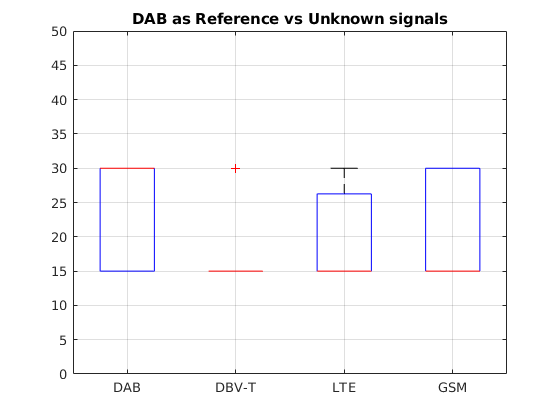

% Plotting
figure(); 
grid on; hold on;
boxplot([dab(1).in10.doa; dab(2).in10.doa; dab(3).in10.doa; dab(4).in10.doa], ...
        [dab(1).in10.labels; dab(2).in10.labels; dab(3).in10.labels; dab(4).in10.labels], ...
        'labels', {dab(1).us, dab(2).us, dab(3).us, dab(4).us});
title('DAB as Reference vs Unknown signals');
ylim([0,50]);
hold off;

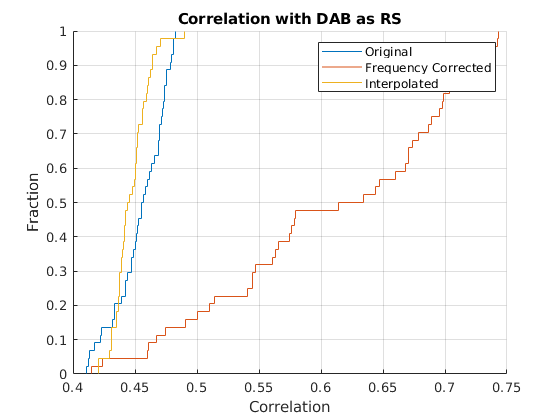

figure(); 
grid on; hold on;
ecdf(dab(1).orig.corr);
ecdf(dab(1).noin.corr);
ecdf(dab(1).in10.corr);
legend('Original', 'Frequency Corrected', 'Interpolated');
title('Correlation with DAB as RS');
xlabel('Correlation'); ylabel('Fraction');
hold off;

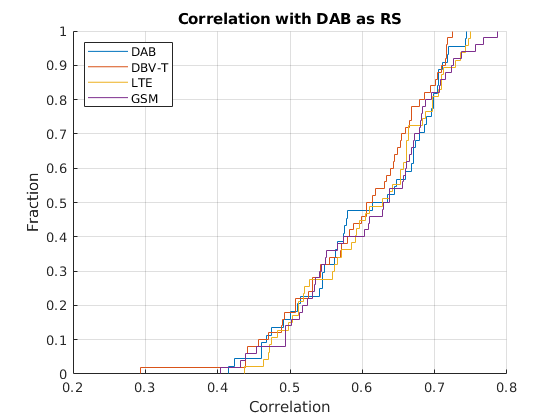

figure();
grid on; hold on;
ecdf(dab(1).noin.corr);
ecdf(dab(2).noin.corr);
ecdf(dab(3).noin.corr);
ecdf(dab(4).noin.corr);
legend(dab(1).us, dab(2).us, dab(3).us, dab(4).us,'Location',"northwest");
title('Correlation with DAB as RS');
xlabel('Correlation'); ylabel('Fraction');
hold off;

## DVB-T

% Main DAB struct
dvbt = struct();

### RS: DVB-T - US: DAB

dvbt(1).us = 'DAB';
load('results/splitter_dvbt_dab_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dvbt(1).orig.doa = abs(doa_meters_2(idx)) + 150; 
dvbt(1).orig.doa_mean = abs(doa_meters(idx)) + 150;
dvbt(1).orig.labels = ones(length(dvbt(1).orig.doa),1)*5;
dvbt(1).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_dab_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(1).noin.doa = abs(doa_meters_2(idx)) + 150;
dvbt(1).noin.labels = ones(length(dvbt(1).noin.doa),1)*5;
dvbt(1).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_dab_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(1).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(1).in10.labels = ones(length(dvbt(1).in10.doa),1)*5;
dvbt(1).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: DVB-T - US: DVB-T

dvbt(2).us = 'DBV-T';
load('results/splitter_dvbt_dvbt_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dvbt(2).orig.doa = abs(doa_meters_2(idx)) + 150; 
dvbt(2).orig.doa_mean = abs(doa_meters(idx)) + 150;
dvbt(2).orig.labels = ones(length(dvbt(2).orig.doa),1)*6;
dvbt(2).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_dvbt_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(2).noin.doa = abs(doa_meters_2(idx)) + 150;
dvbt(2).noin.labels = ones(length(dvbt(2).noin.doa),1)*6;
dvbt(2).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_dvbt_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(2).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(2).in10.labels = ones(length(dvbt(2).in10.doa),1)*6;
dvbt(2).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: DVB-T - US: LTE

dvbt(3).us = 'LTE';
load('results/splitter_dvbt_lte_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dvbt(3).orig.doa = abs(doa_meters_2(idx)) + 150; 
dvbt(3).orig.doa_mean = abs(doa_meters(idx)) + 150;
dvbt(3).orig.labels = ones(length(dvbt(3).orig.doa),1)*7;
dvbt(3).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_lte_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(3).noin.doa = abs(doa_meters_2(idx)) + 150;
dvbt(3).noin.labels = ones(length(dvbt(3).noin.doa),1)*7;
dvbt(3).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_lte_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(3).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(3).in10.labels = ones(length(dvbt(3).in10.doa),1)*7;
dvbt(3).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: DVB-T - US: GSM

dvbt(4).us = 'GSM';
load('results/splitter_dvbt_gsm_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
dvbt(4).orig.doa = abs(doa_meters_2(idx)) + 150; 
dvbt(4).orig.doa_mean = abs(doa_meters(idx)) + 150;
dvbt(4).orig.labels = ones(length(dvbt(4).orig.doa),1)*8;
dvbt(4).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_gsm_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(4).noin.doa = abs(doa_meters_2(idx)) + 150;
dvbt(4).noin.labels = ones(length(dvbt(4).noin.doa),1)*8;
dvbt(4).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_dvbt_gsm_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(4).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(4).in10.labels = ones(length(dvbt(4).in10.doa),1)*8;
dvbt(4).in10.corr = min(correlation_value_interp(idx),[],2);

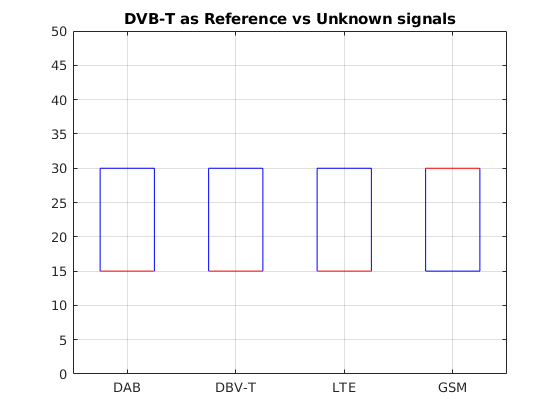

% Plotting
figure(); 
grid on; hold on;
boxplot([dvbt(1).in10.doa; dvbt(2).in10.doa; dvbt(3).in10.doa; dvbt(4).in10.doa], ...
        [dvbt(1).in10.labels; dvbt(2).in10.labels; dvbt(3).in10.labels; dvbt(4).in10.labels], ...
        'labels', {dvbt(1).us, dvbt(2).us, dvbt(3).us, dvbt(4).us});
title('DVB-T as Reference vs Unknown signals');
ylim([0,50]);
hold off;

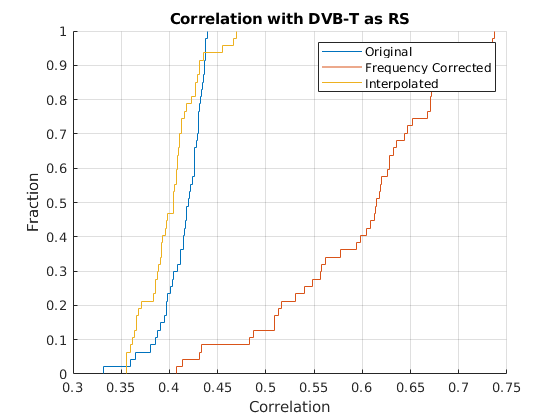

figure(); 
grid on; hold on;
ecdf(dvbt(3).orig.corr);
ecdf(dvbt(3).noin.corr);
ecdf(dvbt(3).in10.corr);
legend('Original', 'Frequency Corrected', 'Interpolated');
title('Correlation with DVB-T as RS');
xlabel('Correlation'); ylabel('Fraction');

## GSM

% Main DAB struct
gsm = struct();

### RS: GSM - US: DAB

gsm(1).us = 'DAB';
load('results/splitter_gsm_dab_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
gsm(1).orig.doa = abs(doa_meters_2(idx)) + 150; 
gsm(1).orig.doa_mean = abs(doa_meters(idx)) + 150;
gsm(1).orig.labels = ones(length(gsm(1).orig.doa),1)*9;
gsm(1).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_dab_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(1).noin.doa = abs(doa_meters_2(idx)) + 150;
gsm(1).noin.labels = ones(length(gsm(1).noin.doa),1)*9;
gsm(1).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_dab_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(1).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(1).in10.labels = ones(length(gsm(1).in10.doa),1)*9;
gsm(1).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: GSM - US: DVB-T

gsm(2).us = 'DBV-T';
load('results/splitter_gsm_dvbt_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
gsm(2).orig.doa = abs(doa_meters_2(idx)) + 150; 
gsm(2).orig.doa_mean = abs(doa_meters(idx)) + 150;
gsm(2).orig.labels = ones(length(gsm(2).orig.doa),1)*10;
gsm(2).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_dvbt_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(2).noin.doa = abs(doa_meters_2(idx)) + 150;
gsm(2).noin.labels = ones(length(gsm(2).noin.doa),1)*10;
gsm(2).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_dvbt_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(2).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(2).in10.labels = ones(length(gsm(2).in10.doa),1)*10;
gsm(2).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: GSM - US: LTE

gsm(3).us = 'LTE';
load('results/splitter_gsm_lte_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
gsm(3).orig.doa = abs(doa_meters_2(idx)) + 150; 
gsm(3).orig.doa_mean = abs(doa_meters(idx)) + 150;
gsm(3).orig.labels = ones(length(gsm(3).orig.doa),1)*11;
gsm(3).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_lte_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(3).noin.doa = abs(doa_meters_2(idx)) + 150;
gsm(3).noin.labels = ones(length(gsm(3).noin.doa),1)*11;
gsm(3).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_lte_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(3).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(3).in10.labels = ones(length(gsm(3).in10.doa),1)*11;
gsm(3).in10.corr = min(correlation_value_interp(idx),[],2);

### RS: GSM - US: GSM

gsm(4).us = 'GSM';
load('results/splitter_gsm_gsm_original_dphase.mat');
idx = min(correlation_value,[],2) > 0.1;
gsm(4).orig.doa = abs(doa_meters_2(idx)) + 150; 
gsm(4).orig.doa_mean = abs(doa_meters(idx)) + 150;
gsm(4).orig.labels = ones(length(gsm(4).orig.doa),1)*12;
gsm(4).orig.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_gsm_fo_correction_no_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(4).noin.doa = abs(doa_meters_2(idx)) + 150;
gsm(4).noin.labels = ones(length(gsm(4).noin.doa),1)*12;
gsm(4).noin.corr = min(correlation_value(idx),[],2);

load('results/splitter_gsm_gsm_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(4).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(4).in10.labels = ones(length(gsm(4).in10.doa),1)*12;
gsm(4).in10.corr = min(correlation_value_interp(idx),[],2);

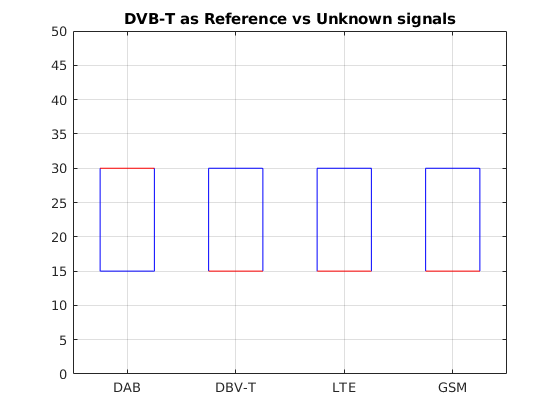

% Plotting
figure(); 
grid on; hold on;
boxplot([gsm(1).in10.doa; gsm(2).in10.doa; gsm(3).in10.doa; gsm(4).in10.doa], ...
        [gsm(1).in10.labels; gsm(2).in10.labels; gsm(3).in10.labels; gsm(4).in10.labels], ...
        'labels', {gsm(1).us, gsm(2).us, gsm(3).us, gsm(4).us});
title('DVB-T as Reference vs Unknown signals');
ylim([0,50]);
hold off;

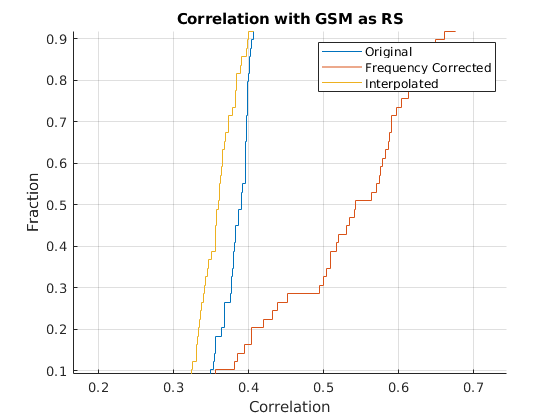

figure(); 
grid on; hold on;
ecdf(gsm(3).orig.corr);
ecdf(gsm(3).noin.corr);
ecdf(gsm(3).in10.corr);
legend('Original', 'Frequency Corrected', 'Interpolated');
title('Correlation with GSM as RS');
xlabel('Correlation'); ylabel('Fraction');
hold off;

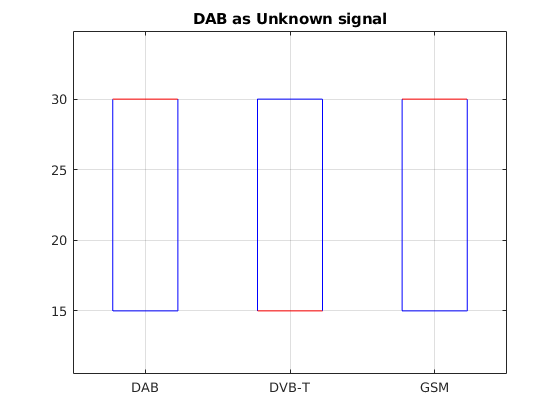

% DAB as unknown
figure();
hold on;
grid on;
boxplot([dab(1).in10.doa; dvbt(1).in10.doa; gsm(1).in10.doa], [dab(1).in10.labels; dvbt(1).in10.labels; gsm(1).in10.labels],...
         'labels',{'DAB','DVB-T','GSM'});
title('DAB as Unknown signal')
hold off;

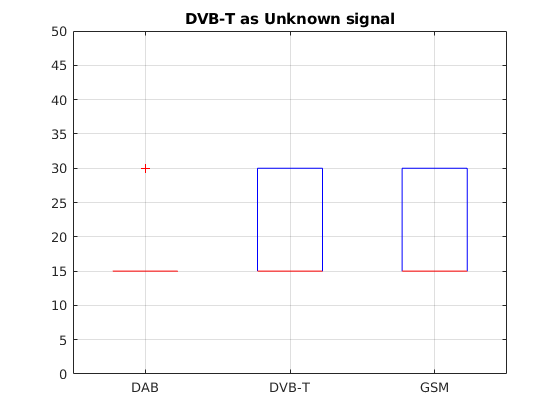

% DVB-T as unknown
figure();
hold on;
grid on;
boxplot([dab(2).in10.doa; dvbt(2).in10.doa; gsm(2).in10.doa], [dab(2).in10.labels; dvbt(2).in10.labels; gsm(2).in10.labels],...
         'labels',{'DAB','DVB-T','GSM'});
title('DVB-T as Unknown signal');
ylim([0,50]);
hold off;

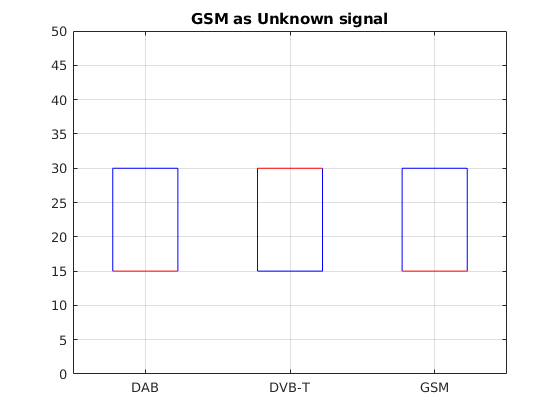

% GSM as unknown
figure();
hold on;
grid on;
boxplot([dab(4).in10.doa; dvbt(4).in10.doa; gsm(4).in10.doa], [dab(4).in10.labels; dvbt(4).in10.labels; gsm(4).in10.labels],...
         'labels',{'DAB','DVB-T','GSM'});
title('GSM as Unknown signal');
ylim([0,50]);
hold off;

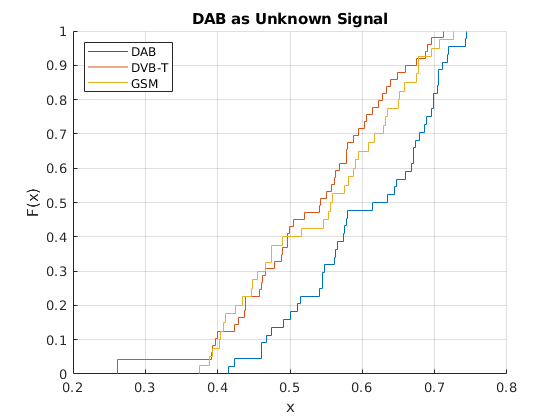

% Comparing correlations
figure();
hold on; grid on;
ecdf(dab(1).noin.corr);
ecdf(dvbt(1).noin.corr);
ecdf(gsm(1).noin.corr);
title('DAB as Unknown Signal');
legend('DAB','DVB-T', 'GSM','Location','northwest');
hold off;

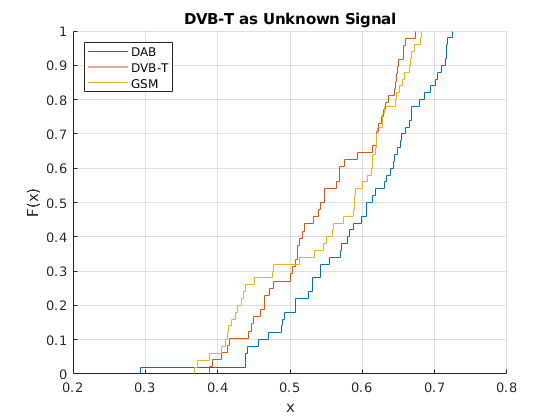

% Comparing correlations
figure();
hold on; grid on;
ecdf(dab(2).noin.corr);
ecdf(dvbt(2).noin.corr);
ecdf(gsm(2).noin.corr);
title('DVB-T as Unknown Signal');
legend('DAB','DVB-T', 'GSM','Location','northwest');
hold off;

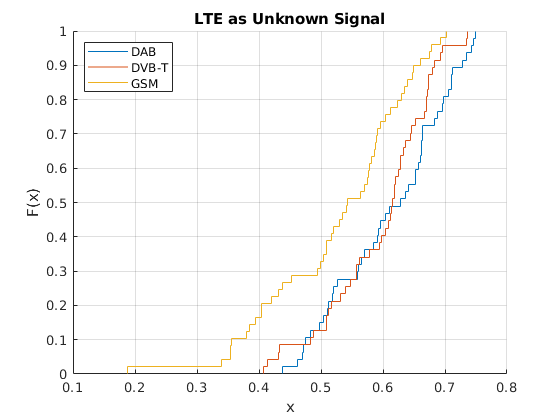

% Comparing correlations
figure();
hold on; grid on;
ecdf(dab(3).noin.corr);
ecdf(dvbt(3).noin.corr);
ecdf(gsm(3).noin.corr);
title('LTE as Unknown Signal');
legend('DAB','DVB-T', 'GSM','Location','northwest');
hold off;

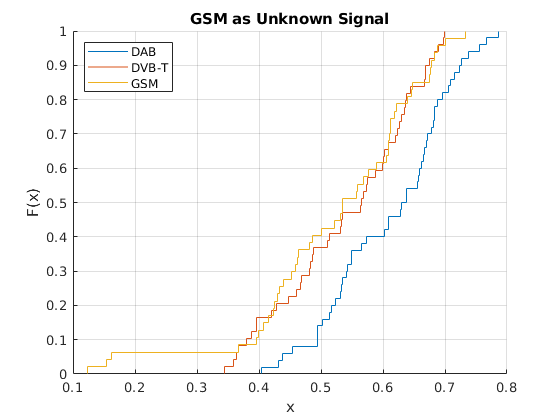

% Comparing correlations
figure();
hold on; grid on;
ecdf(dab(4).noin.corr);
ecdf(dvbt(4).noin.corr);
ecdf(gsm(4).noin.corr);
title('GSM as Unknown Signal');
legend('DAB','DVB-T', 'GSM','Location','northwest');
hold off;